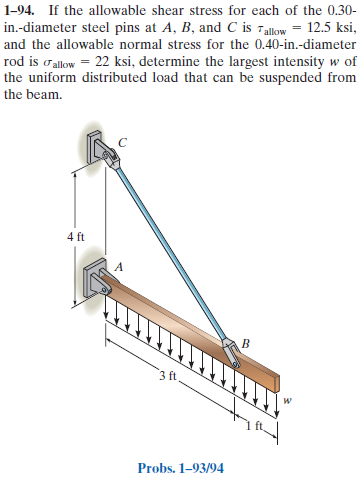

[https://www.chegg.com/homework-help/Mechanics-of-Materials-8th-edition-chapter-1-problem-94P-solution-9780136022305](https://www.chegg.com/homework-help/Mechanics-of-Materials-8th-edition-chapter-1-problem-94P-solution-9780136022305) 

# assumptions

u = symunit;
old_assum = assumptions;
clearassum;

# load data

theta = atand(sym(4/3))*u.deg;
wo = sym('wo');
F_bc = sym('F_bc');
d_bc = 0.40*u.in;
d_pin = 0.30*u.in;
sigma_allow = 22*u.ksi;
tau_allow = 12.5*u.ksi;
wo_sol = default_struct('pin_bc', 'rod_bc', 'pin_a');

# beam

b = beam;
b = b.add('reaction', 'force', 'Ra', 0);
b = b.add('reaction', 'force', F_bc*sin(theta), 3*u.ft);
b = b.add('distributed', 'force', -wo, [0 4]*u.ft);
b.L = 4*u.ft;

# solution

[y dy m v w rs ra hs ha] = b.elastic_curve('Mode', 'factor');

# elastic curve

y

$$y(x) = \left\{ \begin{array}{cl} \frac{\mathrm{wo}\,x\,\left(x-3\,\mathrm{ft}\right)\,\left(-3\,x^{2}+7\,x\,\mathrm{ft}+21\,{\mathrm{ft}}^{2}\right)}{72\,\text{E}\,\text{I}} & \text{ if }x\leq 3\,\mathrm{ft}\\ -\frac{\mathrm{wo}\,\left(x-3\,\mathrm{ft}\right)\,\left(x^{3}-13\,x^{2}\,\mathrm{ft}+57\,x\,{\mathrm{ft}}^{2}-96\,{\mathrm{ft}}^{3}\right)}{24\,\text{E}\,\text{I}} & \text{ if }3\,\mathrm{ft}<x \end{array}\right.$$

dy

$$dy(x) = \left\{ \begin{array}{cl} -\frac{\mathrm{wo}\,\left(4\,x^{3}-16\,x^{2}\,\mathrm{ft}+21\,{\mathrm{ft}}^{3}\right)}{24\,\text{E}\,\text{I}} & \text{ if }x\leq 3\,\mathrm{ft}\\ -\frac{\mathrm{wo}\,\left(4\,x^{3}-48\,x^{2}\,\mathrm{ft}+192\,x\,{\mathrm{ft}}^{2}-267\,{\mathrm{ft}}^{3}\right)}{24\,\text{E}\,\text{I}} & \text{ if }3\,\mathrm{ft}<x \end{array}\right.$$

m

$$m(x) = \left\{ \begin{array}{cl} -\frac{\mathrm{wo}\,x\,\left(3\,x-8\,\mathrm{ft}\right)}{6} & \text{ if }x\leq 3\,\mathrm{ft}\\ -\frac{\mathrm{wo}\,{\left(x-4\,\mathrm{ft}\right)}^{2}}{2} & \text{ if }3\,\mathrm{ft}<x \end{array}\right.$$

v

$$v(x) = \left\{ \begin{array}{cl} -\frac{\mathrm{wo}\,\left(3\,x-4\,\mathrm{ft}\right)}{3} & \text{ if }x\leq 3\,\mathrm{ft}\\ -\mathrm{wo}\,\left(x-4\,\mathrm{ft}\right) & \text{ if }3\,\mathrm{ft}<x \end{array}\right.$$

w

$$w(x) = -\mathrm{wo}$$

# reactions and hinges

ra

$$ra = \left(\begin{array}{cc} F_{\mathrm{bc}} & \frac{10\,\mathrm{wo}}{3}\,\mathrm{ft}\\ \mathrm{Ra} & \frac{4\,\mathrm{wo}}{3}\,\mathrm{ft} \end{array}\right)$$

ha

 
ha =
 
Empty sym: 0-by-2
 


# shear and moment diagrams

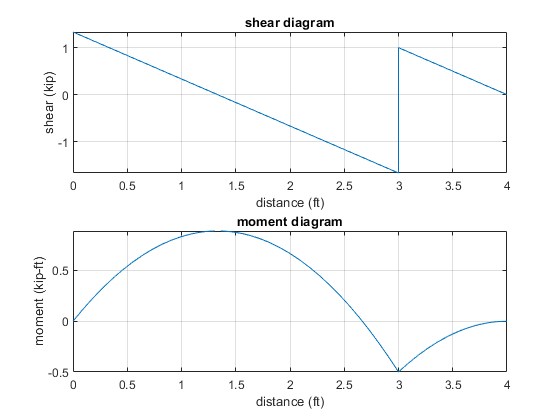

beam.shear_moment(m, v, [0 b.L], wo, 1, {'kip' 'ft'});

# design for pins at points B and C

V_bc = rs.F_bc/2;
A_pin = sympi/4*d_pin^2;
tau_bc(wo) = rewrite(V_bc/A_pin, u.ft);
wo_sol.pin_bc = rewrite(solve(tau_allow == tau_bc), u.kip/u.ft);
wo_sol_pin_bc = vpa(wo_sol.pin_bc, 3) %#ok<NASGU> 

$$wo\_sol\_pin\_bc = 0.53\,\frac{\mathrm{kip}}{\mathrm{ft}}$$

# design for normal stress in rod BC

A_bc = sympi/4*d_bc^2;
P_bc = rs.F_bc;
sigma_bc(wo) = rewrite(rs.F_bc/A_bc, u.ft);
wo_sol.rod_bc = rewrite(solve(sigma_allow == sigma_bc), u.kip/u.ft);
wo_sol_rod_bc = vpa(wo_sol.rod_bc, 3) %#ok<NASGU> 

$$wo\_sol\_rod\_bc = 0.829\,\frac{\mathrm{kip}}{\mathrm{ft}}$$

# design for pin at point A

P_pin = sqrt(rs.F_bc^2*cos(theta)^2+v(0)^2)/2;
P_pin = simplify(P_pin, 'IgnoreAnalyticConstraints', true);
tau_a(wo) = rewrite(P_pin/A_pin, u.ft);
wo_sol.pin_a = rewrite(solve(tau_allow == tau_a), u.kip/u.ft);
wo_sol_pin_a = vpa(wo_sol.pin_a, 3) %#ok<NASGU> 

$$wo\_sol\_pin\_a = 0.735\,\frac{\mathrm{kip}}{\mathrm{ft}}$$

# largest w value

wo_sol_vals = structfun(@sym, wo_sol);
in_range = isAlways(tau_bc(wo_sol_vals) <= tau_allow & ...
                    sigma_bc(wo_sol_vals) <= sigma_allow & ...
                    tau_a(wo_sol_vals) <= tau_allow);
wo_sol.limit = wo_sol_vals(in_range);
wo_sol_limit = vpa(wo_sol.limit, 3) %#ok<NASGU> 

$$wo\_sol\_limit = 0.53\,\frac{\mathrm{kip}}{\mathrm{ft}}$$

# clean up

addvar(y);
assume(old_assum);
clear old_assum;
clear wo_sol_pin_bc;
clear wo_sol_rod_bc;
clear wo_sol_pin_a;
clear wo_sol_limit;